# `stereo2stl`

`Three-dimensional stereo reconstruction.`

Point cloud STL generation from stereo input.

## Dependencies

Install the [`mpm`](https://mathworks.com/matlabcentral/fileexchange/54548-mpm) addon to manage dependencies automatically.

Dependency tree:

- [`surf2stl`](https://mathworks.com/matlabcentral/fileexchange/4512) - Write STL file from surface data.

File: *stereo2stl/script.m*

Brief: *Script for point cloud STL generation from stereo input.*

## Introduction

`stereo2stl` is a MATLAB generator script for stereo reconstruction.

Input: landscape, JPG/JPEG, grayscale stereo images.

- Add checkerboard images from left stereo view to `./calib-left`

- Insert checkerboard images from right stereo view to `./calib-right`

- Add modelling input images from stereo view to `./input`

`   imformats() %  supported images formats in MATLAB`

Output: `point-cloud` file in script location (STL format).

- A 3D representation of the stereo image set.

## Image inputs

Requirements:

- Images should be same orientation as checkerboard to reduce pixel error from reprojection.

- For calibration images, asymmetric (odd-even) checkerboard should be in all views.

- For calibration images, minimum image count per folder is 4 (for low reprojection error).

- For calibration images, naming convention is: `./calib-<VIEW>/<VIEW>##.jpg` (e.g. `./calib-left/left01.jpg`)

Image folders:

- `./input`: actual 3D model target scene.

- `./calib-left`: left stereo view with checkerboard.

- `./calib-right`: right stereo view with checkerboard.

N.B: the image file names must be numbered in ascending order.

The script targets the left & right image in the `./input` folder and converts it into a STL file.

## Source code

### Initialise generator script.

`1. `Cleanup of MATLAB workspace, IDE & output file.

close all;
clear;
clc;

`2. `Show loading indicator.

    Script takes T = ~30s to execute.

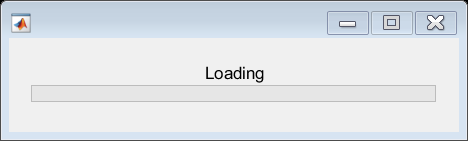

loadingWaitbar = waitbar(0, "Loading");

loadingWaitbar.Visible = "on";

### Script variable configuration.

`1. `Load surf2stl if not installed.

if ~exist("surf2stl", "file")
    if ~matlab.addons.isAddonEnabled("mpm")
        error([                                                             ...
            "Please install MPM as a MATLAB Addon.\n"                       ...
            "<a href="""                                                    ...
            "https://uk.mathworks.com/matlabcentral/fileexchange/54548"     ...
            """>"                                                           ...
            "mpm - File Exchange - MATLAB Central"                          ...
            "</a>"                                                          ...
        ])
    else
        mpm install surf2stl;
    end
end

`2. `User configuration variables.

- `filePath:` path to current folder.

- `stlPath``:` name of point cloud STL.

- `imageMinimum``:` min. no of images in calib folder.

- `approxImageHeight``: `Estimate of furthest scene height in mm.

- `squareWidth``:` Checkerboard square width in mm.

- `ptCloudDensity``: Point density within squareWidth.`

- `sGolayFiltOrder``:` Savitsky-Golay extrapolation curve order.

- `sGolayFiltFrameLen``:` Savitsky-Golay sliding window point count.

filePath = pwd;
stlPath = "point-cloud.stl";
imageMinimum = 3;
squareWidth = 50;
ptCloudDensity = 5;
sGolayFiltOrder = 2;
sGolayFiltFrameLen = 9;

### Camera calibration of stereo images.

Code based on MATLAB `rectifyStereoImages` code sample. [[1]](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

1. Delete STL if it exists.

if exist(fullfile(filePath, stlPath), "file")
    recycle on;
    delete(fullfile(filePath, stlPath));
end

`2.` Load all of our images in one go.

   See ["Image inputs"](#image-inputs).

- `inputImages`: Images from `./input` subfolder.

- `calibLeftImages`: Images from `./calib-left` subfolder.

- `calibRightImages`: Images from `./calib-right` subfolder.

inputImages = imageDatastore(fullfile(filePath, "input"));
calibLeftImages = imageDatastore(fullfile(filePath, "calibration", "left"));
calibRightImages = imageDatastore(fullfile(filePath, "calibration", "right"));
waitbar(0.1, loadingWaitbar);

`3.`` Detect the checkerboards in the original files.`

[imagePoints, boardSize] = detectCheckerboardPoints(                    ...
    calibLeftImages.Files,                                              ...
    calibRightImages.Files                                              ...
);
waitbar(0.2, loadingWaitbar);

`3.` Calculate undistorted, real-world coordinates of checkerboard keypoints.

worldPoints = generateCheckerboardPoints(boardSize, squareWidth);

`4.` Read input images into MATLAB, and convert to grayscale.

   This reduces image data & overhead in calibration phase. [[2]](https://www.mathworks.com/help/matlab/ref/rgb2gray.html)

I1 = readimage(inputImages, 1);
if size(I1, 3) == 3
    I1 = rgb2gray(I1);
end
I2 = readimage(inputImages, 2);
if size(I2, 3) == 3
    I2 = rgb2gray(I2);
end
imageSize = [size(I1, 1), size(I1, 2)];

`5.` Image validation (for camera calibration).

   Throws error if:

- mismatch in image count between `./calib-lef`t & `./calib-right`

- below 4 images in `./calib-left` & `./calib-right`

- mismatch in resolution of `./input` images

imageSize2 = [size(I2, 1), size(I2, 2)];

imageAmounts = struct;
imageAmounts.L = size(calibLeftImages.Files, 1);
imageAmounts.R = size(calibRightImages.Files, 1);

if imageAmounts.L ~= imageAmounts.R      % error #1

    e = sprintf(                                                        ...
        "stereo2stl::ERR_MISMATCH_IMG_COUNT (L: %d, R: %d)",            ...
        imageAmounts.L, imageAmounts.R                                  ...
    );
    errordlg(e);
    error(e); %#ok<*SPERR> 

elseif imageAmounts.L < imageMinimum    % error #2

    e = sprintf("stereo2stl::ERR_CALIB_IMG_INSUFFICIENT (%d)", imageAmounts.L);
    errordlg(e);
    error(e);

elseif ~isequal(imageSize, imageSize2)   % error #3

    e = sprintf(                                                            ...
        "stereo2stl::ERR_MISMATCH_IMG_DIM (L: %dx%dpx, R: %dx%dpx)",    ...
        imageSize(1), imageSize(2), imageSize2(1), imageSize2(2)        ...
    );
    errordlg(e);
    error(e);

end

`6. `Use MATLAB toolbox to calibrate the stereo camera system.

   **Parameters:**

- `EstimateSkew`: Are image axes exactly perpendicular? Default: `true.`

- `EstimateTangentialDistortion`: Factor in whether the camera is horizontal. Default: `true`.

- `NumRadialDistortionCoefficients`: Good for fish-eye lenses. Default: `2`.

- `ImageSize`: Matrix for size of image - `imageSize`.

   **TODO: **Adjust `estimateCameraParameters` parameters for experimental stage.

[stereoParams, ~, estimationErrors] = estimateCameraParameters(         ...
    imagePoints, worldPoints,                                           ...
    "EstimateSkew", true,                                               ...
    "EstimateTangentialDistortion", true                                ...
);
waitbar(0.3, loadingWaitbar);

`7. `Display camera extrinisics for dissertation purposes.

   Figure 1 & 2 - locations & reprojection errors.

   Reprojection is process of "reprojecting" original image from a camera image.

   Most camera images have distortion (e.g. "fisheye" lens effect).

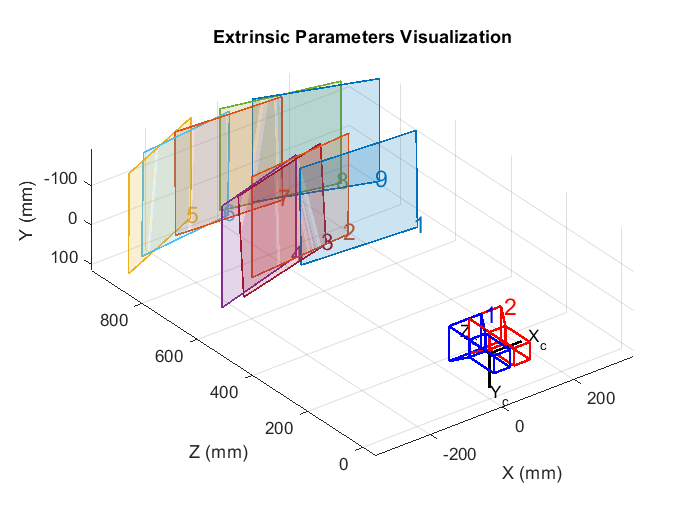

figure;
showExtrinsics(stereoParams, "CameraCentric");

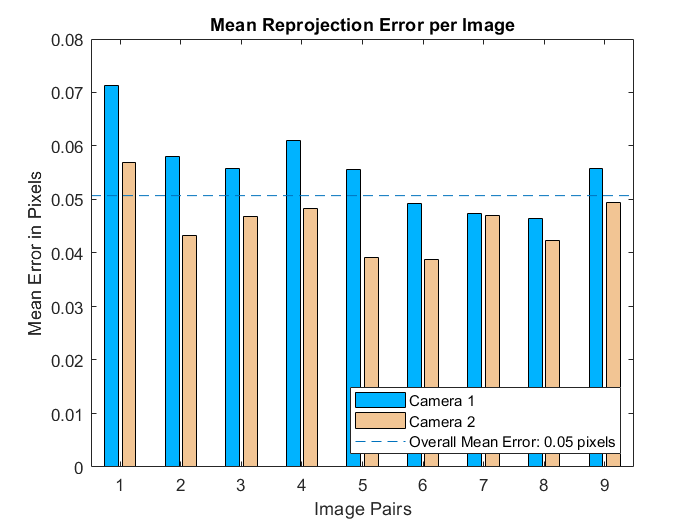

waitbar(0.4, loadingWaitbar);
figure;
showReprojectionErrors(stereoParams);

displayErrors(estimationErrors, stereoParams);


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [ 1033.5919 +/- 0.6166     1033.4438 +/- 0.6085  ]
Principal point (pixels):[  657.7186 +/- 0.3440      481.2812 +/- 0.2710  ]
Skew:                    [    0.4485 +/- 0.0268  ]
Radial distortion:       [   -0.3615 +/- 0.0005        0.1819 +/- 0.0018  ]
Tangential distortion:   [    0.0007 +/- 0.0000       -0.0001 +/- 0.0000  ]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [   -0.1735 +/- 0.0005        0.0246 +/- 0.0004       -3.1610 +/- 0.0000  ]
                         [    0.1995 +/- 0.0005       -0.0551 +/- 0.0004       -3.0985 +/- 0.0000  ]
                         [    0.4196 +/- 0.0005       -0.1093 +/- 0.0004       -3.1104 +/- 0.0001  ]
                         [    0.5256 +/- 0.0004       -0.0638 +/- 0.0003       -3.0542 +/- 0.0001  ]
                         [

waitbar(0.5, loadingWaitbar);

`8. `Rectify the images using "valid" output view.

   The "valid" option is most suitable for computing disparity. [[3]](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

   **Parameters:**

- `OutputView`: OutputView crops the image to a rectangle, fitting inside the overlapping, curved 3D anaglyph. Default: `valid`.

[F1, F2] = rectifyStereoImages(I1, I2, stereoParams, "OutputView", "valid");
pixelDensityMm = mean(                                                  ...
    [                                                                   ...
        stereoParams.CameraParameters1.IntrinsicMatrix(2, 1),           ...
        stereoParams.CameraParameters2.IntrinsicMatrix(2, 1)            ...
    ], 2                                                                ...
);
approxImageHeight = 0.5 * mean(size(F1, 2)) / pixelDensityMm;
waitbar(0.6, loadingWaitbar);

`9. `Display an anaglyph image for "valid" output view.

   Figure 3 - stereo anaglyph.

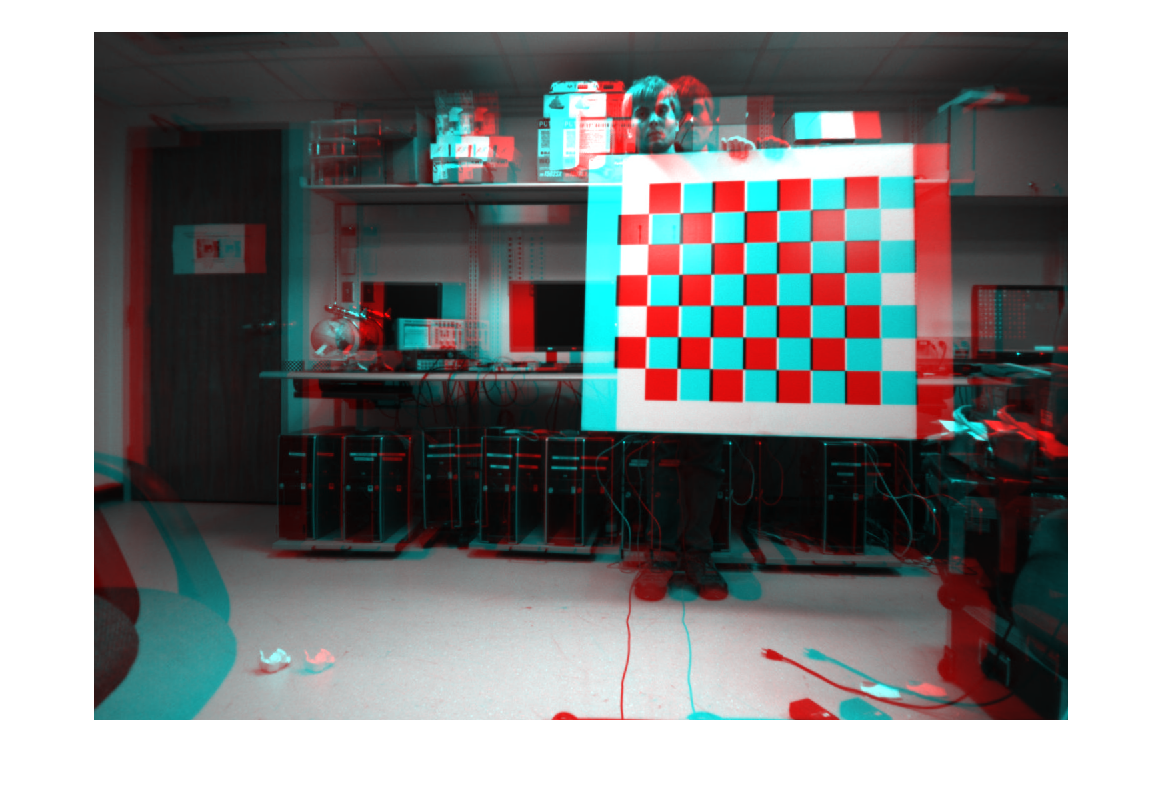

figure;
imshow(stereoAnaglyph(F1, F2));
title 'Rectified Image';

waitbar(0.7, loadingWaitbar);

### Disparity computation from stereo images.

Code based on MATLAB `disparitySGM` code sample. [[4]](https://www.mathworks.com/help/vision/ref/disparitysgm.html)

`1. `Compute disparity map from stereo images (colormap of depth).

disparityMap = disparitySGM(F1, F2, "DisparityRange", [0, 80]);
waitbar(0.8, loadingWaitbar);

`2. `Display disparity map as jet colormap image.

   Figure 4 - disparity map.

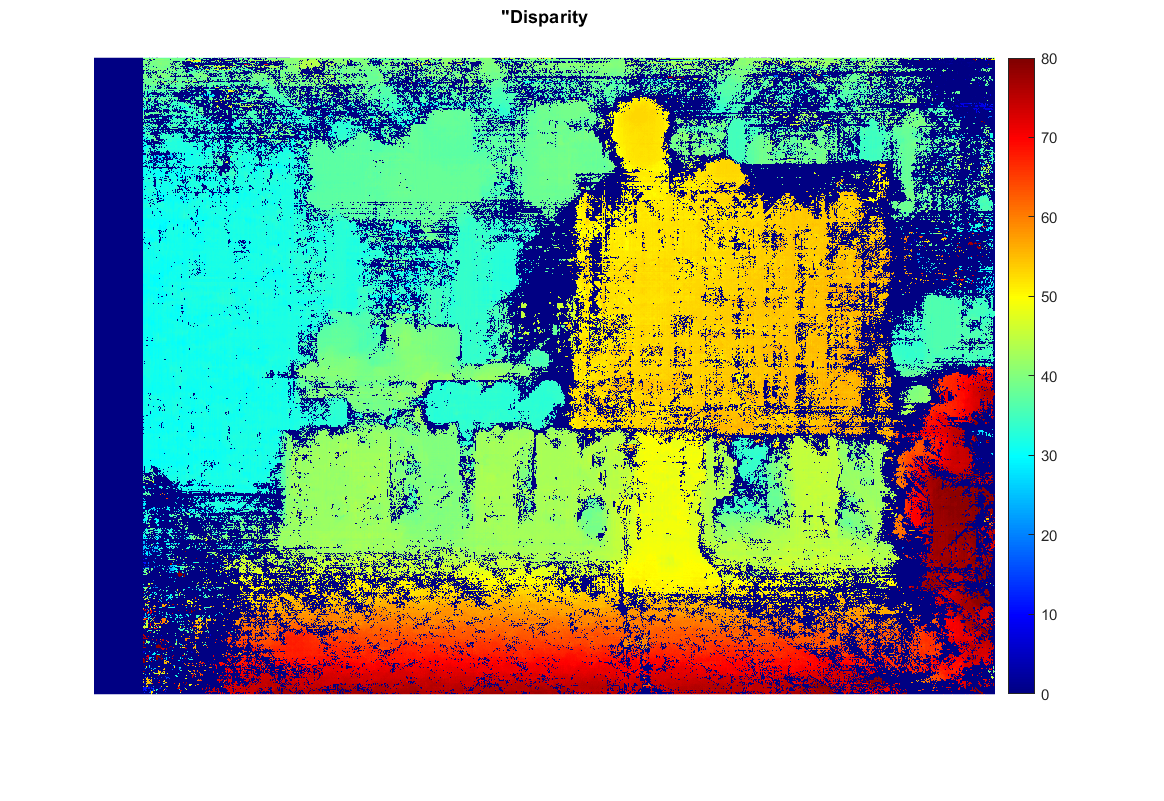

figure;
imshow(disparityMap, [0, 80]);
colormap jet;
title 'Disparity Map';
colorbar;

waitbar(0.9, loadingWaitbar);

### Point cloud generation (using depth data).

`1. `Reconstruct the 3D image input into organised point cache matrix.

   Produces raw point cloud of X-Y-Z data in m - standard STL dimensions.

rawPoints3D = reconstructScene(disparityMap, stereoParams);
rawPoints3D(isinf(rawPoints3D)) = NaN;
rawPoints3D = double(rawPoints3D) ./ 1000;

`2. `Initialise axial, co-ordinate cache for point cloud.

pointsCache = struct;
axesKeys = ["X", "Y", "Z"];
for i = 1:3
    k = char(axesKeys(i));
    p = rawPoints3D(:, :, i);
    pointsCache.(k) = p;
end
clearvars p k;

`3. `Compute checkerboard position as a point cloud.

   It's the closest set of co-ordinates to the origin in the z-axis.

   **TODO:** See if I need to change `min` in some way (assumes convex).

checkerboardCentroid.Z = min(min(pointsCache.Z));
checkerboardIndex = sort(find(checkerboardCentroid.Z == pointsCache.Z));
checkerboardCentroid.X = mean(pointsCache.X(checkerboardIndex));
checkerboardCentroid.Y = mean(pointsCache.Y(checkerboardIndex));

`4. `Restrict point cloud to following conditions:

- point cloud width/2 ~ image height

- point cloud length = point cloud height = point cloud width

limits = struct;
cacheAxes = char(fieldnames(pointsCache));

for i = 1:3
    k = cacheAxes(i);
    lim = [                                                             ...
        checkerboardCentroid.(k) - approxImageHeight/1000,              ...
        checkerboardCentroid.(k) + approxImageHeight/1000               ...
    ];
    limits.(k) = lim;

    p = pointsCache.(k);
    p(p < lim(1) | p > lim(2)) = NaN;
    pointsCache.(k) = p;
end

clearvars k lim p;

`5. `Remove invalid (NaN) values inside point cloud.

- Values that are `+Inf`/`-Inf`/`NaN``.`

- Points that fall outside range of point cloud.

nanPoints = ( 0                                                         ...
    | isnan(pointsCache.X)                                              ...
    | isnan(pointsCache.Y)                                              ...
    | isnan(pointsCache.Z)                                              ...
);

for i = 1:3
    k = cacheAxes(i);
    p = pointsCache.(k);
    p(nanPoints) = checkerboardCentroid.(k);
    pointsCache.(k) = p;
end

clearvars k p;

`6. `Surface mesh denoising and interpolation.

  `See:` [https://commons.wikimedia.org/wiki/File:Lissage_sg3_anim.gif](https://commons.wikimedia.org/wiki/File:Lissage_sg3_anim.gif)

    Code adapted from StackOverflow. [[5]](https://stackoverflow.com/a/39576639)

- The `scatteredInterpolant` factory function computes interpolant. [[6]](https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html)

- MATLAB maps `meshgrid` regular matrix of points for X and Y.

- Savitzky-Golay filter used to denoise points in Z axis.

gs = (1 / ptCloudDensity) * (squareWidth / 1000);

I = scatteredInterpolant(pointsCache.X(:), pointsCache.Y(:), pointsCache.Z(:), "natural");


gridPoints = struct;
intX = min(pointsCache.X(:)):gs:max(pointsCache.X(:));
intY = min(pointsCache.Y(:)):gs:max(pointsCache.Y(:));
[gridPoints.X, gridPoints.Y] = meshgrid(intX, intY);

gridPoints.Z = I(gridPoints.X, gridPoints.Y);
intZ1 = sgolayfilt(gridPoints.Z.', sGolayFiltOrder, sGolayFiltFrameLen);
intZ2 = sgolayfilt(gridPoints.Z, sGolayFiltOrder, sGolayFiltFrameLen);
gridPoints.Z = (intZ1.' + intZ2)/2;

points3D = double.empty();
for i = 1:3
    points3D(:, :, i) = gridPoints.(cacheAxes(i));
end

clearvars cacheAxes;

`7. `Convert 3D points to point cloud.

ptCloud = pointCloud(points3D);

`8. `Launch rotatable, 3D point cloud viewer.

   Figure 5 - scattered point cloud.

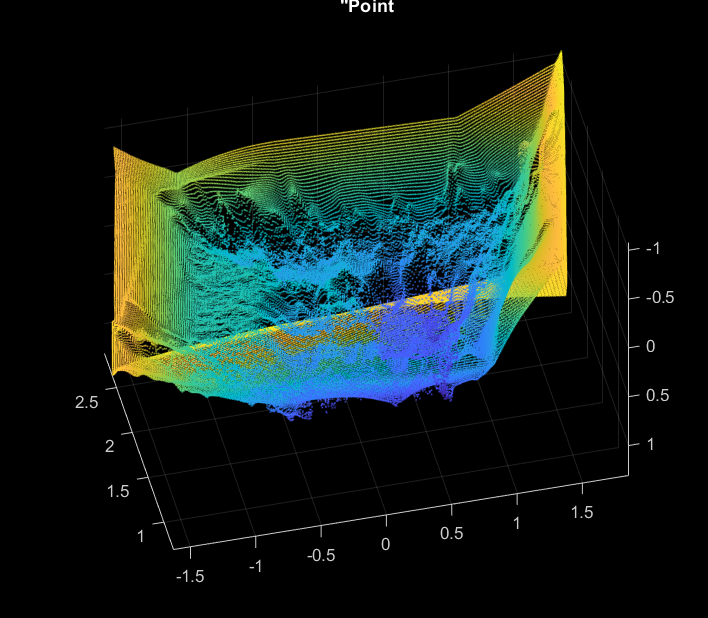

figure;
figure3D = pcshow(ptCloud, "VerticalAxis", "y", "VerticalAxisDir", "down");
movegui(figure3D, "center");
figure3D.OuterPosition = [0 0 1 1];


title 'Point Cloud';
xlabel 'x (horizontal displacement in m)';

Error using xlabel (line 30)
Incorrect number of input arguments.

ylabel 'y (vertical displacement in m)';
zlabel 'z (point depth in m)';

view(0, -90);
set(gcf, "Color", "w");
set(gca, "XColor", "k");
set(gca, "YColor", "k");
set(gca, "ZColor", "k");

colormap(flipud(jet));
caxis(zlim(figure3D));
colorbar(figure3D);
rotate3d on;

waitbar(1, loadingWaitbar);
close(loadingWaitbar);

### STL file generation from point cloud.

Using `surf2stl` for high stability & speed (low interpolation).

stlPath = char(fullfile(filePath, stlPath));
surf2stl(stlPath, gridPoints.X, gridPoints.Y, gridPoints.Z);
winopen(stlPath);

### References.

- [https://www.mathworks.com/help/matlab/ref/rgb2gray.html](https://www.mathworks.com/help/matlab/ref/rgb2gray.html)

- [https://www.mathworks.com/help/vision/examples/depth-estimation-from-stereo-video.html](https://www.mathworks.com/help/vision/examples/depth-estimation-from-stereo-video.html)

- [https://www.mathworks.com/help/vision/ref/rectifystereoimages.html](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

- [https://www.mathworks.com/help/vision/ref/disparitysgm.html](https://www.mathworks.com/help/vision/ref/disparitysgm.html)

- [https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html](https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html)

- [https://stackoverflow.com/a/39576639](https://stackoverflow.com/a/39576639)